addpath('./functions');
addpath('./data');

dataset = [];
classes = [];
for i=1:2
    str = ['data\cifar-10-batches-mat\data_batch_', num2str(i),'.mat'];
    load(str)
    dataset = [dataset; data];
    classes = [classes; labels];

end

load('data\cifar-10-batches-mat\test_batch.mat');

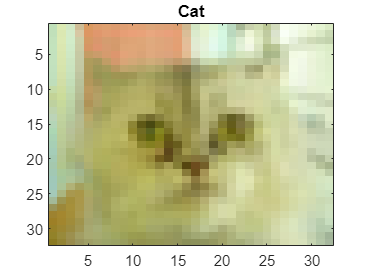

[permutedImageData, categoricalLabels] = permute_dataset(dataset, classes);
labels_names = ["Airplane", ...
                "Automobile", ...
                "Bird", ...
                "Cat", ...
                "Deer", ...
                "Dog", ...
                "Frog", ...
                "Horse", ...
                "Ship", ...
                "Truck", ...
                ];

labels_numbers = ["0", ...
                  "1", ...
                  "2", ...
                  "3", ...
                  "4", ...
                  "5", ...
                  "6", ...
                  "7", ...
                  "8", ...
                  "9", ...
                  ];

label2name = dictionary(labels_numbers, labels_names);
idx = randi(size(permutedImageData,4));

imagesc(permutedImageData(:,:,:,idx))
title(label2name(categoricalLabels(idx)))

% N = size(permutedImageData,4);
% k = round(0.2*N);
% indeces = randperm(N,k);
% permutedImageData = permutedImageData(:,:,:,indeces);
% categoricalLabels = categoricalLabels(indeces);

size(permutedImageData)

ans =           32          32           3       20000


test_size = 0.2

test_size = 0.2000

% normalizedData = normalize(permutedImageData);
[X_train, X_val, Y_train, Y_val] = train_test_split(permutedImageData, categoricalLabels, test_size);

layers = basic_cnn_classifier()

layers =   12×1 Layer array with layers:

     1   ''   Image Input             32×32×3 images with 'zerocenter' normalization
     2   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                    ReLU
     4   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     5   ''   ReLU                    ReLU
     6   ''   2-D Max Pooling         2×2 max pooling with stride [1  1] and padding [0  0  0  0]
     7   ''   2-D Max Pooling         2×2 max pooling with stride [1  1] and padding [0  0  0  0]
     8   ''   Fully Connected         128 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         10 fully connected layer
    11   ''   Softmax                 softmax
    12   ''   Classification Output   crossentropyex

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        9.38% |       10.28% |       2.4658 |       2.3471 |          0.0010 |
|       1 |          10 |       00:00:05 |       29.69% |       18.95% |       2.1516 |       2.2072 |          0.0010 |
|       1 |          20 |       00:00:06 |       15.62% |       23.88% |       2.0822 |       2.1016 |          0.0010 |
|       1 |          30 |       00:00:07 |       28.12% |       27.70% |       1.9461 |       2.0093 |          0.

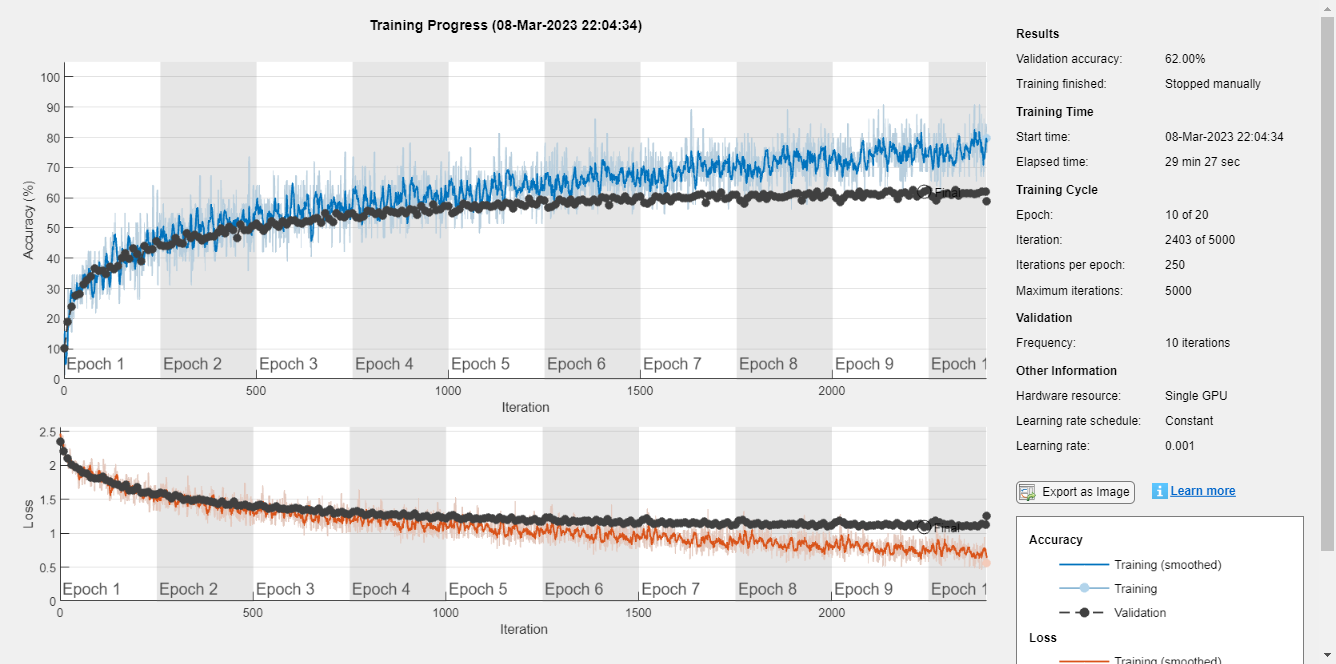

options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",OutputNetwork="best-validation-loss",Plots="training-progress", MiniBatchSize=64, InitialLearnRate=0.001, MaxEpochs=20, ValidationData={X_val,Y_val}, ValidationFrequency=10);
net = trainNetwork(X_train,Y_train, layers, options);

[testData, testLabels] = permute_dataset(data,labels);

preds = net.classify(testData);
tp = nnz(preds == testLabels);
accuracy = tp / length(testLabels);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 62.49%


layers = improved_cnn_classifier();
options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",OutputNetwork="best-validation-loss",Plots="training-progress", MiniBatchSize=64, InitialLearnRate=0.001, MaxEpochs=20, ValidationData={X_val,Y_val}, ValidationFrequency=10);
net = trainNetwork(X_train,Y_train, layers, options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |        6.25% |       10.90% |       3.7158 |       3.1649 |          0.0010 |
|       1 |          10 |       00:00:04 |       10.94% |       25.77% |       2.7366 |       2.3383 |          0.0010 |
|       1 |          20 |       00:00:06 |       29.69% |       31.98% |       2.0631 |       2.0111 |          0.0010 |
|       1 |          30 |       00:00:07 |       32.81% |       34.48% |       1.9449 |       1.8507 |          0.

preds = net.classify(testData);
tp = nnz(preds == testLabels);
accuracy = tp / length(testLabels);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 57.88%
